# 6. High-Level State Control using Stateflow

Even simple robots have several operating states like moving, idle, startup, charging. Depending on the state, the robot should behave differently. I.e. for a balancing robot, we could imagine states like balancing, fallen (idle), calibration, startup.

The robot should be able to change between these states based on sensor measurements or user input. Such a state machine can be implemented using Stateflow.

For the operation of the mini segway, we would like to switch it on and then lay it on the table or floor. During this phase the robot should not drive the motors and just be idle. Once we move the robot into the upright position, it should recognize if we pass a threshold angle and then switch into the balancing mode. This means we need a state machine with two to start with.

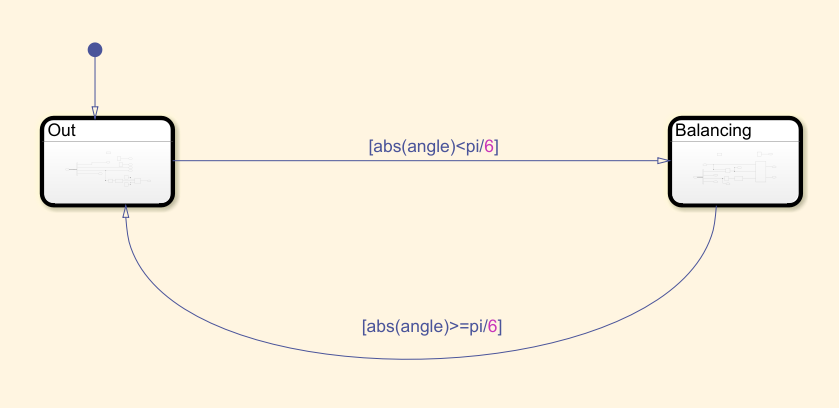

The behavior of each state can either be modeled by using code or a simulink model. To fazilitate the data streaming inside the controls algorithm we use the latter.

#### Idle State

In this state the robot is not balancing and the PosEnc is set to zero. This is required to not have an offset if we put the robot back to balancing mode.

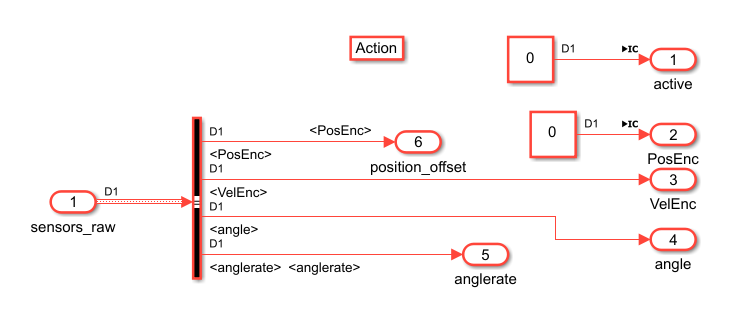

#### Balancing State

Updates the position offset. this is the offset between the initialization of the position encoder and the real encoder value. If the robot falls the current position will be assigned to the offset variable.

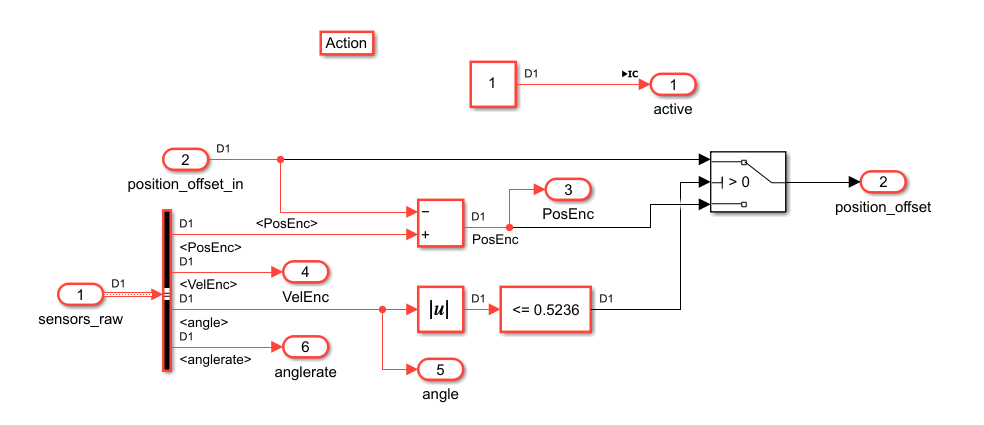

## Validation of the Statemachine

The statemachine has been implemented in the following model. The canvas also includes toggles that can be used to manipulate the robot during simulation. Use them to validate the behavior of the statemachine.

E.g. start the simulation and then switch off the controller. -> The robot should fall down and the controller is switched off (via the "active" signal). Then give a speed pulse to move and stop the robot. If you move the robot at the right speed it will turn over when you stop it.

If you have the controller on during this maneuver, the robot should start balancing again. 

open_system("Ex8_StateMachine")